# PreLab4 

Ali Saeizadeh

810196477

## Bit Generator

b = bit_gen(15,4)

b =      0     1     0     1
     1     1     0     0
     1     1     1     0
     1     0     0     0
     1     0     1     0
     0     1     1     1
     1     0     1     1
     0     0     0     0
     0     0     1     0
     1     1     1     1


## Constellations

[cons, Es_avg] = constellation(4, 'qam');
Es_avg

Es_avg = 1.0000

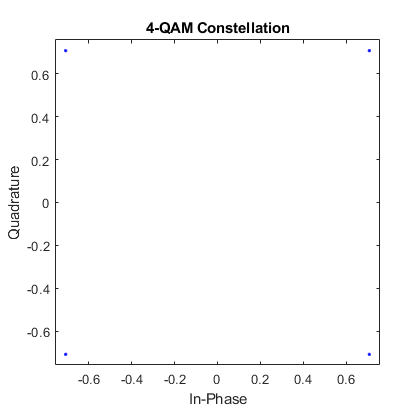

scatterplot(cons);
title('4-QAM Constellation')

[cons, Es_avg] = constellation(4, 'psk');
Es_avg

Es_avg = 1

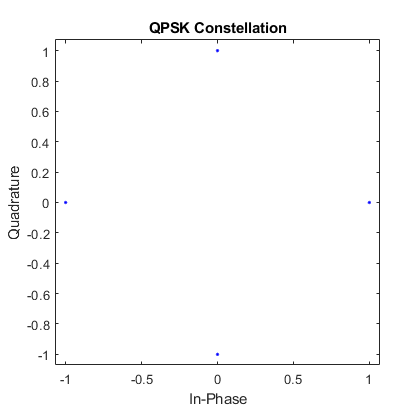

scatterplot(cons);
title('QPSK Constellation')

[cons, Es_avg] = constellation(8, 'pam');
Es_avg

Es_avg = 1.0000

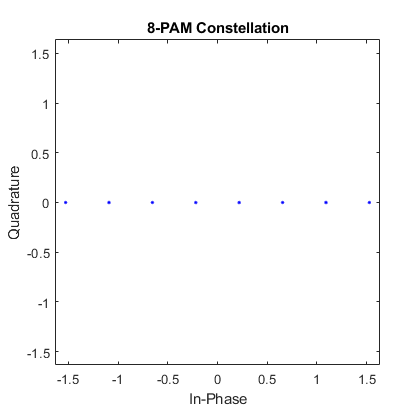

scatterplot(cons);
title('8-PAM Constellation')

[cons, Es_avg] = constellation(16, 'psk');
Es_avg

Es_avg = 1

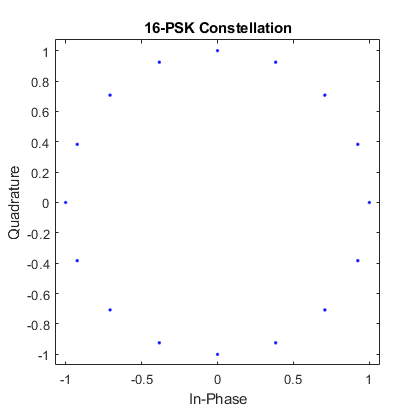

scatterplot(cons);
title('16-PSK Constellation')

[cons, Es_avg] = constellation(32, 'qam');
Es_avg

Es_avg = 1.0000

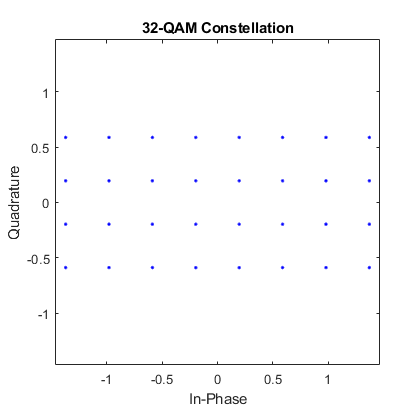

scatterplot(cons);
title('32-QAM Constellation')

[cons, Es_avg] = constellation(8, 'qam');
Es_avg

Es_avg = 1.0000

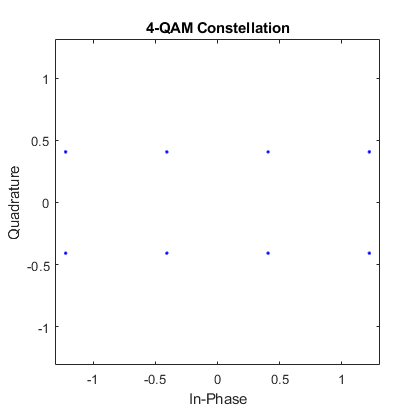

scatterplot(cons);
title('4-QAM Constellation')

## Pulse Shaping

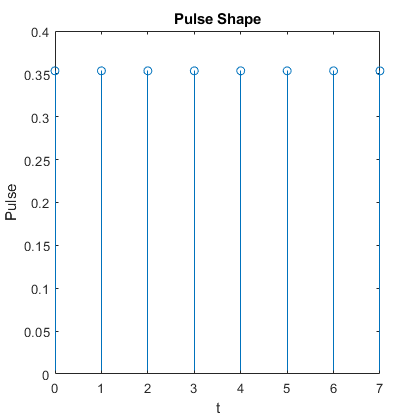

fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
[p, t] = pulse_shape('rectangular', fs, smpl_per_symbl);
stem(t,p)
title('Pulse Shape')
xlabel('t')
ylabel('Pulse')

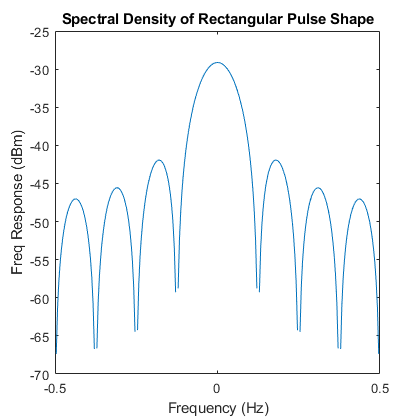

[s, freq] = spectral_dens(p, fs, n_fft);
plot(freq, s)
title('Spectral Density of Rectangular Pulse Shape')
xlabel('Frequency (Hz)')
ylabel('Freq Response (dBm)')

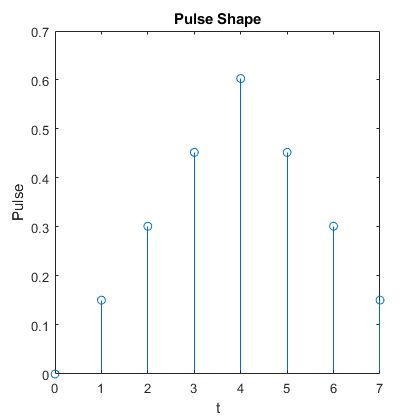

fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
[p, t] = pulse_shape('triangle', fs, smpl_per_symbl);
stem(t,p)
title('Pulse Shape')
xlabel('t')
ylabel('Pulse')

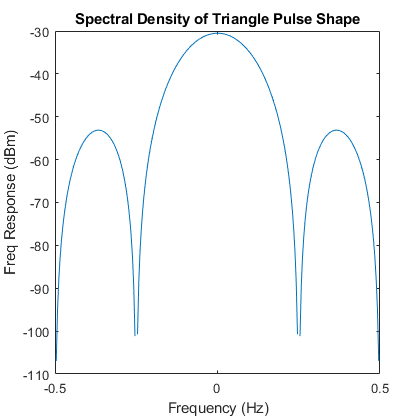

[s, freq] = spectral_dens(p, fs, n_fft);
plot(freq, s)
title('Spectral Density of Triangle Pulse Shape')
xlabel('Frequency (Hz)')
ylabel('Freq Response (dBm)')

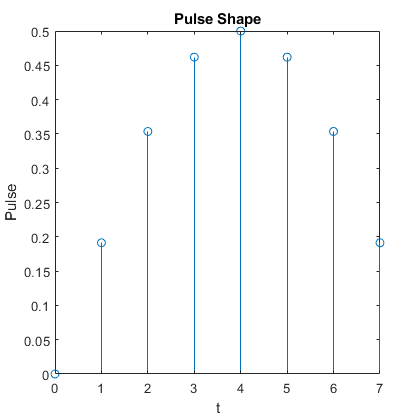

fs = 1;
smpl_per_symbl = 8;
n_fft = 256;
[p, t] = pulse_shape('sine', fs, smpl_per_symbl);
stem(t,p)
title('Pulse Shape')
xlabel('t')
ylabel('Pulse')

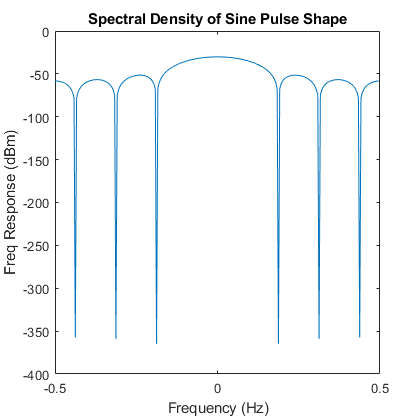

[s, freq] = spectral_dens(p, fs, n_fft);
plot(freq, s)
title('Spectral Density of Sine Pulse Shape')
xlabel('Frequency (Hz)')
ylabel('Freq Response (dBm)')